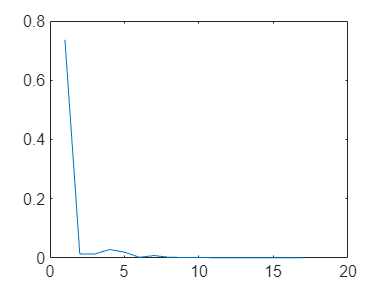


A = 0.32345;
B = -0.78743;
C = 0.56532;
Y = (A+B)*C;
err = [];
for i = 0:1:16 
    
    sign=1; %0-unsigned value, 1-signed value % sign
    prec_i=1; %number of integer part bits (Nc) % one bit
    prec_f=i; %number of fractional part bits (Nu) % eight bits
    word = 1 + prec_i + prec_f; % whole word
    value_A = fi(A,sign,word,prec_f);
    value_B = fi(B,sign,word,prec_f);
    value_C = fi(C,sign,word,prec_f);
    y_aprox = (value_A+value_B)*value_C;
    err(i+1) = abs(double(y_aprox) - Y);
end
plot(err)

sign=1; 
prec_i=1;
prec_f=5;
word = 1 + prec_i + prec_f;
value_A = fi(A,sign,word,prec_f);
value_B = fi(B,sign,word,prec_f);
value_C = fi(C,sign,word,prec_f);
y_aprox = (value_A+value_B)*value_C;
bin(value_A)

ans = '0001010'

bin(value_B)

ans = '1100111'

bin(value_C)

ans = '0010010'

bin((value_A+value_B))

ans = '11110001'

bin(y_aprox)

ans = '111111011110010'

A=-100.34;
B=7.367;
C=-4.92;
D=9.111;
E=-99.99;
F=134.56;
Y = (A+B)*C + (D + E)*(E+F)

Y = -2.6843e+03

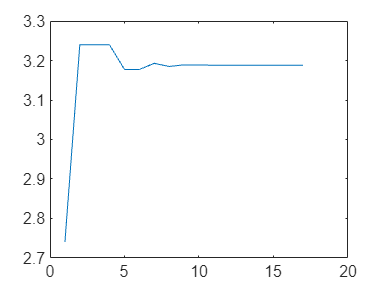

err = [];
for i = 0:1:16 
    
    sign=1; %0-unsigned value, 1-signed value % sign
    prec_i=1; %number of integer part bits (Nc) % one bit
    prec_f=i; %number of fractional part bits (Nu) % eight bits
    word = 1 + prec_i + prec_f; % whole word
    value_A = fi(A,sign,18,8);
    value_B = fi(B,sign,8,3);
    value_C = fi(C,sign,12,7);
    value_D = fi(D,sign,8,2);
    value_E = fi(E,sign,14,5);
    value_F = fi(F,sign,19,9);
    y_aprox_ = (value_A+value_B)*value_C + ((value_D+value_E)*(value_F+value_E));
    y_aprox = fi(y_aprox_,sign,20+i,i);
    err(i+1) = abs(double(y_aprox) - Y);
end
plot(err)

bin(value_A)

ans = '111001101110101001'

bin(value_B)

ans = '00111011'

bin(value_C)

ans = '110110001010'

bin(value_D)

ans = '00100100'

bin(value_E)

ans = '11001110000000'

bin(value_F)

ans = '0010000110100011111'

bin(fi(y_aprox_,sign,20,0)) %with round

ans = '11111111010110000001'

bin(fi(y_aprox_,sign,21,1)) %without round

ans = '111111110101100000001'